# Regresión por mínimos cuadrados

La toma de datos durante una experimentación o durante un análisis se ve siempre afectada por los **errores** que puedan existir debido a **variables que no podemos controlar** y de las cuales desconocemos su comportamiento. Los datos resultantes podrían presentar **errores inerentes al fenómeno** que estudiamos y por lo tanto no siguen **la tendencia** que se esperaría. Es por ello que, en lugar de utilizar una interpolación entre los puntos, se requiere de **una aproximación** bajo una tendencia que esté de acuerdo **al modelo matemático** que describa el fenómeno observado.

## Regresión lineal

A uno de los** métodos** para ajusta el modelo aproximado a los datos obtenidos se le conoce como **regresión por mínimos cuadrados**. El ejemplo mas sencillo se da cuando queremos ajustar la tendencia de una linea recta a un conjunto de datos, en este caso al método se le conoce como **regresión lineal**. 

Supongmos que queremos ajustar una linea recta a los puntos $(x_0,y_0),\,(x_1,y_1),\,...\,,\,(x_n,y_n)$ en un fenómeno donde mediomos una variable $y$ y controlamos una variable $x$. La expresión que mejor describe una tendencia lineal es de la forma 


$$y=a_0+a_1\,x+e$$


 donde $a_0$ y $a_1$ son la ordenada al origen y la pendiende, respectivamente; y $e$ es la diferencia entre el modelo lineal y el conjunto de datos. También se puede entender como la diferencia del valor real con el valor aproximado por la recta. Es decri, para conjunto de datos de la forma $(x_i,y_i)$, estará asociado un error $e_i$ que será la diferencia para "alcanzar" el punto sobre una recta que contiene a todos los puntos promedio de la froma $(\hat{x},\hat{y})$.

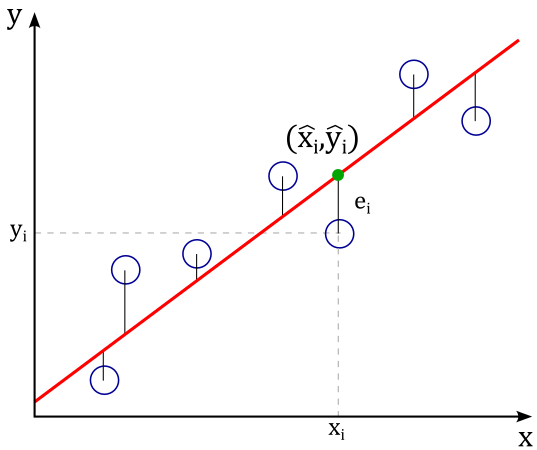

De las diferentes formas de estimar este error, existe una a partir de la cual podemos obtener una única recta para ese conjunto de datos, y se basa en considerar la suma del cuadrado de todos los errores,


$$S_r=\sum_{i=1}^ne_i^2=\sum_{i=1}^n(y_i-\hat{y_i})^2=\sum_{i=1}^n(y_i-a_0-a_1x_i)^2$$


para que de esta forma, las distancias entre las mediciones $y_i$ y el modelo lineal $\hat{y_i}$, puedan ser minimizada.

Debido a que buscamos una única recta cuya distancia sea mínima a todos los puntos, la ecuación antenrior se minimiza con respecto a los coeficientes $a_0$ y $a_1$, es decir, las derivadas parciales con respecto a estas variables deben ser cero. De estas derivadas se obtiene un sistema de dos ecuaciones a partir de las cuales se obtienen los valores para cada constante.


$$\frac{\partial S_r}{\partial a_0}=\sum y_i-\sum a_0-\sum a_1x_i=0$$



$$\frac{\partial S_r}{\partial a_1}=\sum y_ix_i-\sum a_0x_i-\sum a_1x_i^2=0$$


de donde 


$$a_0=\bar{y}-a_1\bar{x}$$



$$a_1=\frac{n\sum x_iy_i-\sum x_i\sum y_i}{n\sum x_i^2-(\sum x_i)^2}$$


% Datos proporcionados
x_lineal = [1, 2, 3, 4, 5, 6, 7];
y_lineal = [0.5, 2.5, 2.0, 4.0, 3.5, 6.0, 5.5];

% Cálculo de las sumas necesarias
n = length(x_lineal);
sum_x = sum(x_lineal);
sum_y = sum(y_lineal);
sum_xy = sum(x_lineal .* y_lineal);
sum_x2 = sum(x_lineal .^ 2);

% Cálculo de los coeficientes
b = (n * sum_xy - sum_x * sum_y) / (n * sum_x2 - sum_x^2);
a = (sum_y - b * sum_x) / n;

% Predicciones
y_pred = a + b * x_lineal;

% Cálculo del coeficiente de determinación R²
SS_res = sum((y_lineal - y_pred).^2);  % Suma de cuadrados de los residuos
SS_tot = sum((y_lineal - mean(y_lineal)).^2); % Suma de cuadrados total
R2 = 1 - (SS_res / SS_tot);     % Coeficiente de determinación

% Mostrar resultados
fprintf('Ecuación de la recta: y = %.4f + %.4fx\n', a, b);
fprintf('Coeficiente a (intercept): %.4f\n', a);
fprintf('Coeficiente b (pendiente): %.4f\n', b);
fprintf('Coeficiente de determinación R²: %.4f\n', R2);

% Predicción para x=8 como ejemplo
x_pred = 8;
y_pred = a + b * x_pred;
fprintf('Predicción para x=%d: y = %.4f\n', x_pred, y_pred);

% Gráfico de los datos y la recta de regresión
figure;
scatter(x_lineal, y_lineal, 'filled'); % Diagrama de dispersión de los datos
hold on;
plot(x_lineal, a + b*x_lineal, 'r');   % Línea de regresión
xlabel('x_i');
ylabel('y_i');
title(['Regresión Lineal (R² = ', num2str(R2, '%.4f'), ')']);
grid on;
legend('Datos', 'Ajuste lineal', 'Location', 'northwest');

Usando la función de ajuste de regresión linealcon la función *fitlm *que funciona cuando los datos estan en formato de tabla.

% Datos
x_lineal = [1, 2, 3, 4, 5, 6, 7]';
y_lineal = [0.5, 2.5, 2.0, 4.0, 3.5, 6.0, 5.5]';

% Crear tabla de datos (requerido por fitlm)
tbl = table(x_lineal, y_lineal, 'VariableNames', {'x', 'y'});

% Ajustar modelo lineal
modelo = fitlm(tbl, 'y ~ x');
% Gráfico con línea de regresión
figure;
plot(modelo);
title('Regresión Lineal usando fitlm');
grid on;

En virtud de que la linea recta representa **una media** para todos los valores alrededro de ella, la desviación estandar de esta acumulación de puntos alrededor de la recta se obtiene de 


$$s=\sqrt{\frac{S_r}{n-2}}$$


denominado el **error estandar** para los datos usados sin considerar las estimaciones de los coeficientes $a_0$ y $a_1$ debido a que estos corresponde a dos de los $n$ puntos usados en la estimación.

Otra forma para determinar la efectividad del ajuste se obtiene de comparar $S_t=\sum(y_i-\bar{y})^2$ la suma del cuadroado de las diferencias entre el valor $y_i$ de cada uno de los puntos con el promedio de estos contra los residuos del ajuste definidos como $S_r=\sum(y_i-a_0-a_1x_i)^2$. A este parámetro se le conoce como el** coeficiente de determinación** y se define como


$$r^2=\frac{S_t-S_r}{S_t}$$


Este valor está **acotado entre 0 y 1** de tal forma que si el ajuste de la regresión lineal "pasa" sobre todos los puntos entonces no existiran residuos, es decir $S_r=0$ y por lo tanto $r^2=1$, mientras que si los residuos corresponden a una exactamente a la diferencia de la cada punto $y_i$ y la media $\bar{y}$, entonces $S_t=S_r$ y por lo tanto $r^2=0$, es decir, no podemos respresentar la tendencia de nuestros datos por medio de una linea recta.

% Datos proporcionados
x_lineal = [1, 2, 3, 4, 5, 6, 7]';
y_lineal = [0.5, 2.5, 2.0, 4.0, 3.5, 6.0, 5.5]';

% 1. Regresión lineal
p = polyfit(x_lineal, y_lineal, 1);
y_pred = polyval(p, x_lineal);
residuos = y_lineal - y_pred;
sigma = std(residuos);

% 2. Crear figura principal
figure;
set(gcf, 'Position', [100, 100, 800, 600], 'Color', 'w');

% Gráfica principal
main_ax = axes('Position', [0.1 0.1 0.8 0.8]);
scatter(x_lineal, y_lineal, 'filled', 'b');
hold on;
plot(x_lineal, y_pred, 'r-', 'LineWidth', 2);
title(['Regresión Lineal: y = ', num2str(p(2), '%.4f'), ' + ', num2str(p(1), '%.4f'), 'x']);
xlabel('x_i');
ylabel('y_i');
grid on;
legend('Datos', 'Ajuste lineal', 'Location', 'northwest');
axis tight;

% 3. Crear distribución gaussiana para el inset
x_gauss = linspace(-3*sigma, 3*sigma, 200);
y_gauss = normpdf(x_gauss, 0, sigma);
y_gauss = y_gauss/max(y_gauss)*0.8; % Normalizar altura

% 4. Crear inset rotado
inset_pos = [0.6 0.61 0.25 0.25]; % Posición y tamaño del inset
inset_ax = axes('Position', inset_pos);

% Rotar y graficar la gaussiana (30 grados)
theta = -atand(p(1))-10; % Ángulo de rotación en grados

[x_rot, y_rot] = rotate_curve(x_gauss, y_gauss, theta);

fill(x_rot, y_rot, [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'EdgeColor', 'k', 'LineWidth', 1);
hold on;

% Configurar el inset
set(inset_ax, 'Color', 'none', 'XTick', [], 'YTick', [], 'XColor', 'none', 'YColor', 'none');
axis equal;
axis off;

## Ejemplo

Supongamos la caida de un objeto dentro de la atmósfera. Se han tomado los datos de la velocidad de su ingreso.

% Crear un arreglo de tiempo de 1 a 15 segundos
tiempo = (1:15)';

% Datos de velocidad medida
v_medida = [10.00; 16.30; 23.00; 27.50; 31.00; 35.60; 39.00; 41.50; 42.90; 45.00; 46.00; 45.50; 46.00; 49.00; 50.00];

% Crear una tabla con los datos
tabla_datos = table(tiempo, v_medida, 'VariableNames', {'Tiempo_s', 'v_medida_m_s'});

% Mostrar la tabla
disp(tabla_datos);

Se estima que un modelo para el movimiento de este cuerpo es de la forma $v_{1}(t)=\frac{gm}{c}\left(\frac{t}{3.75+t}\right)$. Por otro lado, considerando el modelo de caida libre con fricción en una ecuación diferencial, la solución será de la forma $v_{2}(t)=\frac{gm}{c}\left(1-e^{-(c/m)t}\right)$.

g=9.8;  %la aceleración de la gravedad
m=68.1; %masa del cuerpo
c=12.5; %coeficiente de arrastre
v1 = @(t)  (g*m/c)*(t./(3.75+t)); %modelo 1 de velocidad
v1_modelo=v1(tiempo);
v2 = @(t)  (g*m/c)*(1-exp(-c*t/m)); %modelo 2 de velocidad
v2_modelo=v2(tiempo);
tabla_modelo=table(tiempo, v1(tiempo), v2(tiempo),'VariableNames', {'Tiempo (s)', 'v modelo 1 (m/s)', 'v modelo 2 (m/s)'});
disp(tabla_modelo);
figure;
hold on
plot(tiempo, v1(tiempo),'o')
plot(tiempo,v_medida,'o')
plot(tiempo,v2(tiempo),'d')
hold off

Para evaluar el grado de coincidencia entre los modelos y los datos podemos graficar $v_{medida}\; vs\;v_{modelo\,1}$y $v_{medida}\; vs\;v_{modelo\,2}$. El ajuste lineal por medio de una regresión lineal no daría información de la precisión del modelo; de tal forma que los coeficientes de la pendiente y la ordenada al origen deben ser 1 y 0 respectivamente cuando el modelo coincida con la medición y el coeficiente de determinación $r2=1$. Del ajuste de las gráficas, el coeficiente de determinación para cada modelo nos dirá que tan cercano es a la realidad.

% Crear tabla de datos (requerido por fitlm)
tbl1 = table(v_medida, v1_modelo, 'VariableNames', {'x', 'y'});
tbl2 = table(v_medida, v2_modelo, 'VariableNames', {'x', 'y'});
% Ajustar modelo lineal
modelo1 = fitlm(tbl1, 'y ~ x');
modelo2 = fitlm(tbl2, 'y ~ x');

% Extraer coeficientes y R²
b0_lin1 = modelo1.Coefficients.Estimate(1);  % Ordenada al origen
b1_lin1 = modelo1.Coefficients.Estimate(2);  % Pendiente
R2_lin1 = modelo1.Rsquared.Ordinary;

b0_2 = modelo2.Coefficients.Estimate(1);
b1_2 = modelo2.Coefficients.Estimate(2);
R2_2 = modelo2.Rsquared.Ordinary;

% Crear gráfica
figure;
hold on;
grid on;

% Graficar modelos físicos
plot(modelo1);
plot(modelo2);

% Graficar rectas de regresión (ajustadas)
plot(v_medida, v1_modelo, 'g:', 'LineWidth', 2, 'DisplayName', sprintf('Ajuste 1: y = %.2fx + %.2f\nR² = %.4f', b1_1, b0_1, R2_1));
plot(v_medida, v2_modelo, 'm-.', 'LineWidth', 2, 'DisplayName', sprintf('Ajuste 2: y = %.2fx + %.2f\nR² = %.4f', b1_2, b0_2, R2_2));

% Añadir leyenda y formato
legend('Location', 'best', 'FontSize', 10);
xlabel('Tiempo (s)', 'FontSize', 12);
ylabel('Velocidad (m/s)', 'FontSize', 12);
title('Comparación de modelos y ajustes lineales', 'FontSize', 14);
hold off;

## Linealización

En ocasiones, encontraremos que los datos no siguen una tendencia lineal por lo que tendremos que modificarlos para que puedan visualizarse como una línea recta.

% Datos de la tabla
x_lineal = [1, 2, 3, 4, 5];
y_lineal = [0.5, 1.7, 3.4, 5.7, 8.4];

% Aplicar transformación logarítmica base 10 a y
x_log= log10(x_lineal);
y_log = log10(y_lineal);

% Ajuste lineal a los datos NO transformados
p_lineal = polyfit(x_lineal, y_lineal, 1);
a_lineal = p(2); % Intercepto
b_lineal = p(1); % Pendiente

% Ajuste lineal a los datos transformados
p = polyfit(x_log, y_log, 1);
a = p(2); % Intercepto
b = p(1); % Pendiente

% Crear figura con dos subgráficas
figure;

% Subgráfica 1: Datos originales
subplot(1,2,1);
scatter(x_lineal, y_lineal, 'filled', 'b');
hold on;
plot(x_lineal, polyval(p_lineal, x_lineal), 'b-', 'LineWidth', 1.5);
plot(x_lineal, y_lineal, 'b--');
title('Datos Originales');
xlabel('x');
ylabel('y');
grid on;
legend('Datos crudos', 'Location', 'northwest');

% Subgráfica 2: Datos transformados y ajuste lineal
subplot(1,2,2);
scatter(x_log, y_log, 'filled', 'r');
hold on;
plot(x_log, polyval(p, x_log), 'r-', 'LineWidth', 1.5);
title('Datos Linealizados (log_{10}(y) vs x)');
xlabel('x');
ylabel('log_{10}(y)');
grid on;
legend('Datos transformados', ['Ajuste lineal: ' sprintf('log_{10}(y) = %.3f + %.3fx', a, b)], ...
       'Location', 'none', 'Position', [0.8, .2, 0.3, 0.1]);

% Mostrar ecuación de ajuste
fprintf('Ecuación linealizada: log10(y) = %.4f + %.4f*x\n', a, b);
fprintf('Pendiente (b): %.4f\n', b);
fprintf('Intercepto (a): %.4f\n', a);

% Calcular R²
y_log_pred = polyval(p, x_log);
SS_res = sum((y_log - y_log_pred).^2);
SS_tot = sum((y_log - mean(y_log)).^2);
R2 = 1 - (SS_res / SS_tot);
fprintf('Coeficiente de determinación R²: %.4f\n', R2);

### Ejemplo (anterior)

El primer modelo usado tiene la forma $v_{1}(t)=\alpha\left(\frac{t}{\beta+t}\right)$. Ahora queremos linealizar este modelo para encontrar el valor de estas constantes. Para el caso de esta función ocuparemos el cambio de variable $t'=\frac{1}{t}$ y $v'(t')=\frac{1}{v(t)}$. De esta sustitución obtenemos que $v'(t)=\frac{1}{\alpha}+\frac{\beta}{\alpha}t'$.

%Sustitución
t_prima=1./tiempo;
v_prima=1./v_medida;

tbl_lin1= table(t_prima, v_prima, 'VariableNames', {'x', 'y'});
% Ajustar modelo lineal
modelo_lin1 = fitlm(tbl_lin1, 'y ~ x');

% Extraer coeficientes y R²
b0_lin1 = modelo_lin1.Coefficients.Estimate(1);  % Ordenada al origen
b1_lin1 = modelo_lin1.Coefficients.Estimate(2);  % Pendiente
R2_lin1 = modelo_lin1.Rsquared.Ordinary;

%Gráfica
figure;
hold on
plot(modelo_lin1)
plot(t_prima, v_prima, 'g:', 'LineWidth', 2, 'DisplayName', sprintf('Ajuste 1: y = %.2fx + %.2f\nR² = %.4f', b1_lin1, b0_lin1, R2_lin1));
% Añadir leyenda y formato
legend('Location', 'best');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Comparación de modelos de velocidad');
hold off;

Y por otro lado, el segundo modelo que se obtiene de desarrollar la ecuacion diferencial es de la forma $v(t)=\alpha(1-e^{\beta t})$. Esta sustitución no es posible hacerla directamente por lo que se necesita conocer un valor estimado de una de la constante $\alpha$ ya que $z=ln\left(1-\frac{v}{\alpha}\right)$ y $z=-\beta t$

%Sustitución
t_prima=tiempo;

% a_estimado = max(v_medida) * 1.05;
a_estimado = g*m/c;
v_prima = log(1 - v_medida ./ a_estimado);

tbl_lin2= table(t_prima, v_prima, 'VariableNames', {'x', 'y'});
% Ajustar modelo lineal
modelo_lin2 = fitlm(tbl_lin2, 'y ~ x');

% Extraer coeficientes y R²
b0_lin2 = modelo_lin2.Coefficients.Estimate(1);  % Ordenada al origen
b1_lin2 = modelo_lin2.Coefficients.Estimate(2);  % Pendiente
R2_lin2 = modelo_lin2.Rsquared.Ordinary;

%Gráfica
figure;
hold on
plot(modelo_lin2)
% plot(t_prima, v_prima, 'b-', 'LineWidth', 2, 'DisplayName', sprintf('Modelo 1: v(t) = (a)+(bt)\nR² = %.4f', R2_lin1));
plot(t_prima, v_prima, 'g:', 'LineWidth', 2, 'DisplayName', sprintf('Ajuste 1: y = %.2fx + %.2f\nR² = %.4f', b1_lin2, b0_lin2, R2_lin2));
% Añadir leyenda y formato
legend('Location', 'best');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Comparación de modelos de velocidad');
hold off;

## Ajuste polinamial

En el caso de que la linealzación no sea la manera mas adecuada para transformar los datos, un ajuste polinomal sería lo mas adecuado. El numero de ecuaciones necesarias para minimizar el orden el error dependerá del grado del polinómino de tal forma que si el modelo tiene una forma


$$y=a_0+a_1x+a_2x^2+...+a_mx^m+e$$


Entonces se necesitarían $m+1$ ecuaciones provenientes de las derivadas $\frac{\partial S_r}{\partial a_0},...\,,\frac{\partial S_r}{\partial a_m}$, de donde la minimización se obteniendo una matriz para el sistema de ecuaciones de $m+1\times m+1$ dimensiones:


$$\left[ \begin{array}{cccc}n & \sum x_i &\cdots& \sum x_i^m \\ 
\sum x_i & \sum x_i^2 &\cdots& \sum x_i^{m+1} \\
\vdots&\vdots&\ddots&\vdots\\ 
\sum x_i^m & \sum x_i^{m+1} &\cdots& \sum x_i^{m^2} \end{array} \right]
\left(\begin{array}{c}
a_0\\
a_1\\
\vdots\\
a_m
\end{array}\right)=
\left(\begin{array}{c}
\sum y_i \\ 
\sum x_iy_i \\
\vdots\\ 
\sum x_i^my_i 
\end{array}\right)$$


que es posible resolverla usando el método de Gauss-Jordan. Este problema está resuelto con la función *polifit*. 

## Regresión lineal múltiple

Cuando se tienen mas de una variable tambien es posible realizar una regresión lineal para ajustar un plano a los puntos.

### Ejemplo 

% Datos de entrada
x1 = [0; 2; 2.5; 1; 4; 7];
x2 = [0; 1; 2; 3; 6; 2];
y = [5; 10; 9; 0; 3; 27];

% Mostrar los datos en forma de tabla
tabla_datos=table(x1, x2, y,'VariableNames', {'x1', 'x2', 'y'});
disp(tabla_datos);
% Construir la matriz de diseño A y el vector b
A = [ones(size(x1)), x1, x2];
b = y;

% Mostrar las matrices
disp('Matriz de diseño A:');
disp(A);
disp('Vector b:');
disp(b);

% Calcular las sumas necesarias
n = length(x1);
sum_x1 = sum(x1);
sum_x2 = sum(x2);
sum_y = sum(y);
sum_x1x1 = sum(x1.^2);
sum_x1x2 = sum(x1.*x2);
sum_x1y = sum(x1.*y);
sum_x2x2 = sum(x2.^2);
sum_x2y = sum(x2.*y);

% Mostrar las sumas
sumas=table(n, sum_x1,sum_x2,sum_y,sum_x1x2,sum_x1x2,sum_x1y,sum_x2x2,sum_x2y,'VariableNames', {'n', 'Σx1', 'Σx2','Σy','Σx1²','Σx1x2','Σx1y','Σx2²','Σx2y'});
disp(sumas);

% Construir el sistema de ecuaciones normales
M = [n, sum_x1, sum_x2;
     sum_x1, sum_x1x1, sum_x1x2;
     sum_x2, sum_x1x2, sum_x2x2];
 
c = [sum_y; sum_x1y; sum_x2y];

% Mostrar el sistema de ecuaciones normales
disp('Sistema de ecuaciones normales (M * coef = c):');
disp('Matriz M:');
disp(M);
disp('Vector c:');
disp(c);

% Resolver el sistema para obtener los coeficientes
coef = M \ c;

% Mostrar los coeficientes del plano
disp('Coeficientes del plano (a0, a1, a2):');
disp(coef);

% Ecuación del plano: y = a0 + a1*x1 + a2*x2
a0 = coef(1);
a1 = coef(2);
a2 = coef(3);

fprintf('\nEcuación del plano ajustado:\n');
fprintf('y = %.4f + %.4f*x1 + %.4f*x2\n', a0, a1, a2);

% Calcular los valores predichos
y_pred = a0 + a1*x1 + a2*x2;

% Calcular el error cuadrático medio
mse = mean((y - y_pred).^2);
fprintf('Error cuadrático medio: %.4f\n', mse);

% Graficar los puntos y el plano ajustado
figure;
scatter3(x1, x2, y, 100, 'filled', 'r');
hold on;

% Crear malla para el plano
[x1_grid, x2_grid] = meshgrid(linspace(min(x1)-1, max(x1)+1, 20), ...
                             linspace(min(x2)-1, max(x2)+1, 20));
y_grid = a0 + a1*x1_grid + a2*x2_grid;

% Graficar el plano
surf(x1_grid, x2_grid, y_grid, 'FaceAlpha', 0.5);
colormap('cool');

% Etiquetas y título
xlabel('x1');
ylabel('x2');
zlabel('y');
title('Ajuste de plano a puntos en 3D');
legend('Puntos originales', 'Plano ajustado', 'Location', 'best');
grid on;
hold off;

# Ejercicio

De los datos proporcionados, calcula la aceleración y desaceleración promedio del metro entre dos estaciones.

% load("D:\Drive @gmail\MATLAB_Online\MobileSensorData/sensorlog_20250319_182513.mat")
% url = 'https://github.com/ArnaldoHC/Herramientas-Computacionales-Avanzadas/raw/498db9030cf94ace36e12014acb45b41873494b9/Clases/sensorlog_20250319_182513.mat';
url = 'https://github.com/ArnaldoHC/Herramientas-Computacionales-Avanzadas/raw/717fb51a62058a2968f76f8eea982ab7080e4252/Clases/aceleracion.dat';
filename = 'aceleracion.dat'; % Nombre local del archivo descargado
websave(filename, url);
load(filename)

x_ejem = aceleracion(: , 1);
y_ejem = aceleracion(: , 2);
z_ejem = aceleracion(: , 2);
t=[1:length(x_ejem)];

mag_a=sqrt(x_ejem.^2+y_ejem.^2+z_ejem.^2);
figure;
subplot(1,4,1)
plot(t,x_ejem)
subplot(1,4,2)
plot(t,y_ejem)
subplot(1,4,3)
plot(t,z_ejem)
subplot(1,4,4)
plot(t,mag_a)

function [xr, yr] = rotate_curve(x, y, theta)
    theta_rad = deg2rad(theta);
    rot_mat = [cos(theta_rad) -sin(theta_rad); sin(theta_rad) cos(theta_rad)];
    rotated = rot_mat * [x; y];
    xr = rotated(1,:);
    yr = rotated(2,:);
end